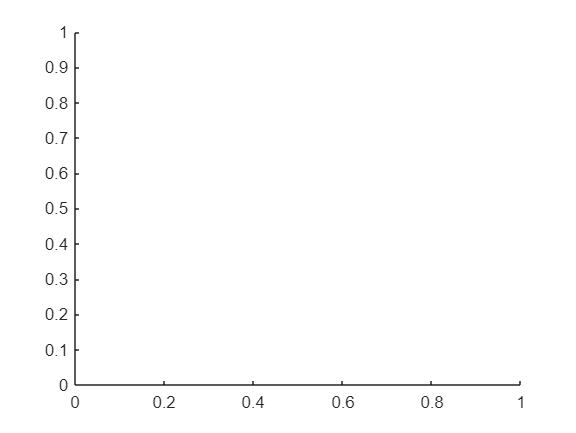

clear all
clc
hold on

%Definición de los datos, en este ejemplo del SPR205
Voc=43.062;
Isc=5.5807;
Imp=5.1280;
Vmp=35.079;
T=54.80;
Ns=72;
G=1000;
%Tolerancia del error
Tol=0.0001

Tol =    1.0000e-04


%Ejemplo lectura de la curva curva del SPR205
Ie= transpose(xlsread('SPR205.xlsx','1 kW','l11:l70'));
Ve= transpose(xlsread('SPR205.xlsx','1 kW','F11:F70'));
%Constantes físicas
q=1.60218*10^(-19);
K=1.380649*10^(-23);
%Calculo Vth 
Vth=Ns*K*(T+273.15)/q;
%Valores iniciales en función del módulo
%Valores para el KC200GT
%Rs1=0.219;
%Rsh1=933.3;
%Valores para el PWP201
%Rs1=1.78;
%Rsh1=600;
%Valores para el RTC
%Rs1=0.02;
%Rsh1=17;
%Valores para los módulos SPR205 y SPR220
Rs1=0.2;
Rsh1=500;
%Se define un error para iniciar el proceso que sea mayor que la tolerancia
err=10;
iter=0;
%Procedimiento de Obbadi
while (err>Tol)
    iter=iter+1;
    n=(Vmp+Imp*Rs1-Voc)/(Vth*log(((Isc-Imp)*(Rs1+Rsh1)-Vmp)/(Isc*(Rs1+Rsh1)-Voc)));
    A=log((n*Vth*Imp*(Rs1+Rsh1)-n*Vth*Vmp)/(Vmp*Isc*(Rsh1+Rs1)-Imp*Rs1*Isc*(Rs1+Rsh1)+Voc*(Rs1*Imp-Vmp)));
    Rs=(Voc-Vmp+Vth*n*A)/Imp;
    Rsh=(n*Vth*(Rsh1+Rs)+Rs*(Isc*(Rsh1+Rs)-Voc)*exp((Isc*Rs-Voc)/(n*Vth))) /(n*Vth+(Isc*Rsh1-Voc+Isc*Rs)*exp((Isc*Rs-Voc)/(n*Vth)));
    err1=100*abs((Rs-Rs1)/Rs);
    err2=100*abs((Rsh-Rsh1)/Rsh);
    %El método no parte de ningún valor inicial de n, por esto se crea este if else
    if (iter==1)
    err3=0;
    else
    err3=100*abs((n-n1)/n);
    end
    err=[err1,err2,err3];
    err=max(err);
    Rs1=Rs;
    Rsh1=Rsh;
    n1=n;
end

Io=(Isc*Rsh+Isc*Rs-Voc)/(Rsh*exp(Voc/(n*Vth)));
Iph=Io*(exp(Voc/(n*Vth))-1)+Voc/Rsh;
%Mostrar parámetros
n

n =    1.3306e+00


Rsh

Rsh =    6.9293e+02


Rs

Rs =    1.7393e-01


iter

iter =         5345


Io

Io =    6.8267e-07


Iph

Iph =    5.5821e+00


%Cálculos de puntos de la curva I-V con los parámetros hallados
for i=1:length(Ve)
   clear I    
    syms I
    eqn1=I==Iph-Io*(exp((Ve(i)+I*Rs1)/(n*Vth))-1)-(Ve(i)+I*Rs1)/Rsh;
    Ik=vpasolve(eqn1,I);
    Isol(i)=double(Ik);
end
%Obtención del RMSE
RMSE=rmse(Isol,Ie)/Isc*100;